# Lab 4

Importing data...

h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);

## Problem 1

In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays.

As with most data, there are 'features.' Your lab instructor has helpfully incorporated the meta-data into your data file.

1) Down load the data from the course website (gammaray_lab4.h5), and import it into your working environment. The data has 4 columns and more than 25 million rows. The columns are time (in gps seconds), Solar phase (deg) showing the position of the sun relative to the orbit, Earth longitude (deg) giving the position of the spacecraft relative to the ground, and particle counts. Make a few plots, generally exploring your data and making sure you understand it. Give a high level description of the data features you see. Specifically comment on whether you see signal contamination in your data, and how you plan to build a background pdf().

Columns = time, solar phase, earth longitude, counts

see how counts are changing with each variable

time = mydata(:,1);
solphase = mydata(:,2);
earthlong = mydata(:,3);
counts = mydata(:,4);

Some basic plots versus time

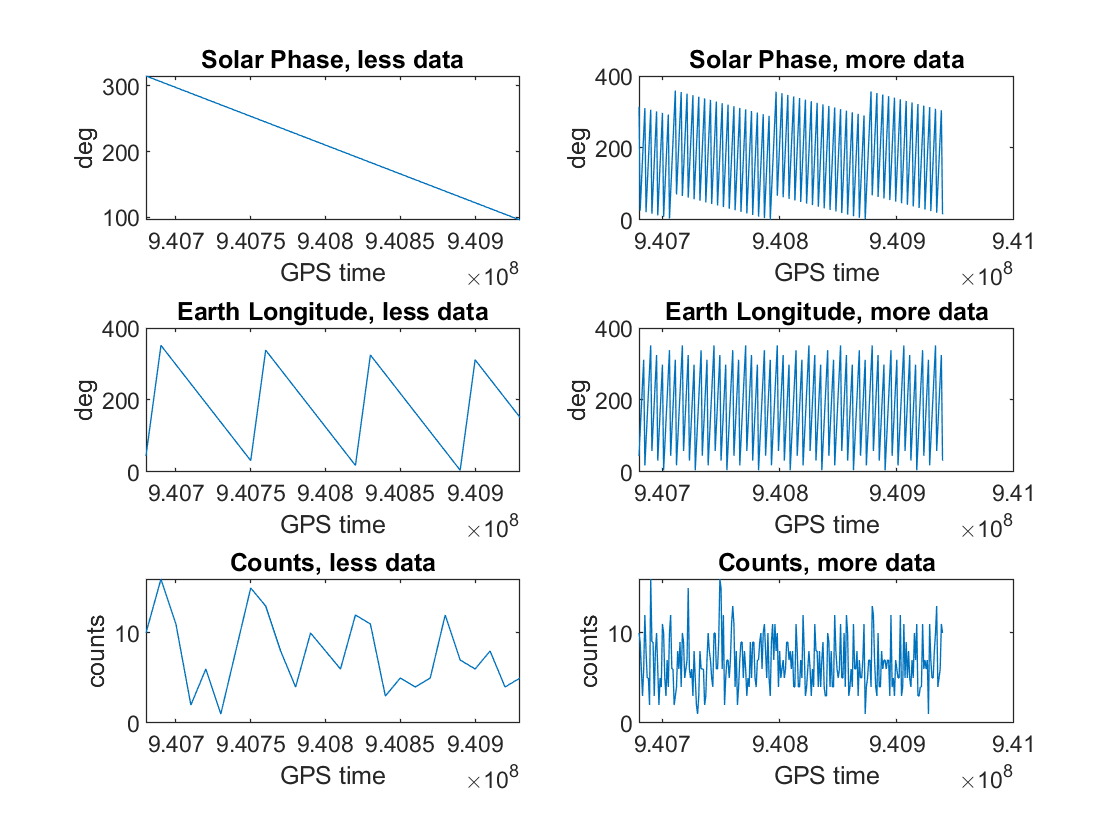

smallsp = (1:100000:2592001);
widesp = (1:10000:2592001);
subplot(3,2,1)
plot(time(smallsp),solphase(smallsp))
title('Solar Phase, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,2)
plot(time(widesp),solphase(widesp))
title('Solar Phase, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,3)
plot(time(smallsp),earthlong(smallsp))
title('Earth Longitude, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,4)
plot(time(widesp),earthlong(widesp))
title('Earth Longitude, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,5)
plot(time(smallsp),counts(smallsp))
title('Counts, less data')
xlabel('GPS time')
ylabel('counts')
subplot(3,2,6)
plot(time(widesp),counts(widesp))
title('Counts, more data')
xlabel('GPS time')
ylabel('counts')

OBSERVATIONS!!

- what do the graphs look like? Periodic? Random? 

- Outliers??

- Look at max and mins of data

now for a counts versus other stuff histogram portion of this lab

% subplot(1,1,1)
% histogram2(solphase,counts,'DisplayStyle','tile')
% colorbar

% subplot(1,1,1)
% histogram2(earthlong,counts,'DisplayStyle','tile')
% colorbar

There seems to be a correlation between counts and Earth Longitude. In the graph, there's a distinct jump around 315-325 degrees. Since the longitude appears to be periodic with time, the start of the 'period' may not be 0. Judging by the graph, it seems to start at that jump. Considering the > 320 region to the left of 0, there seems to be some form of decay, with a sharp decline early on that flattens out to a straight line. 

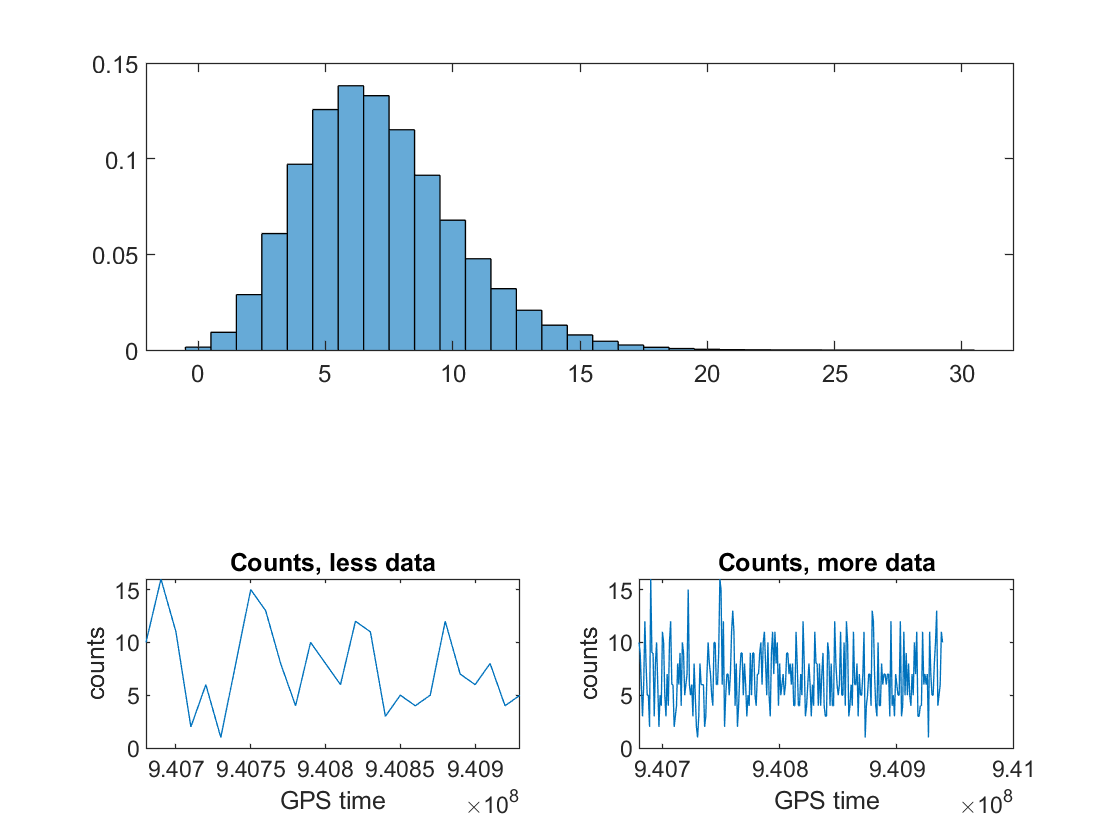

subplot(2,1,1)
histogram(counts,'Normalization','pdf')
subplot(2,1,2)

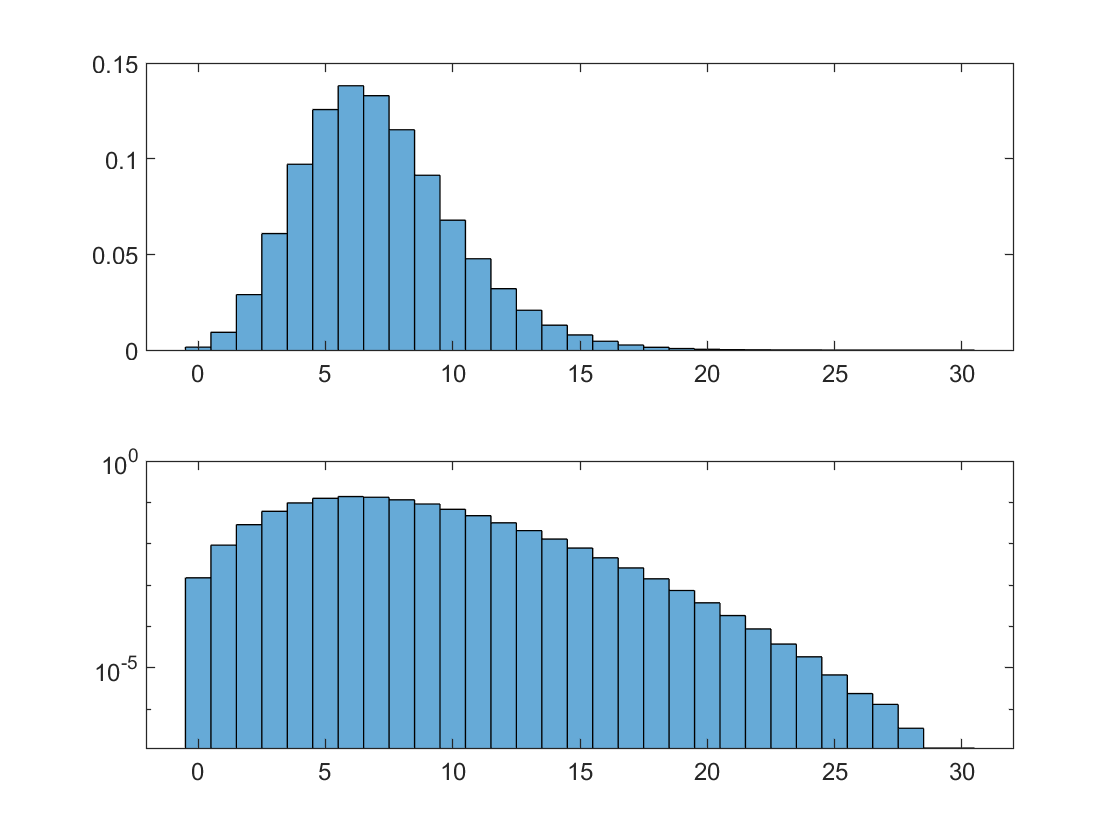

histogram(counts,'Normalization','pdf')
set(gca,'Yscale','log')



lam = mean(counts);

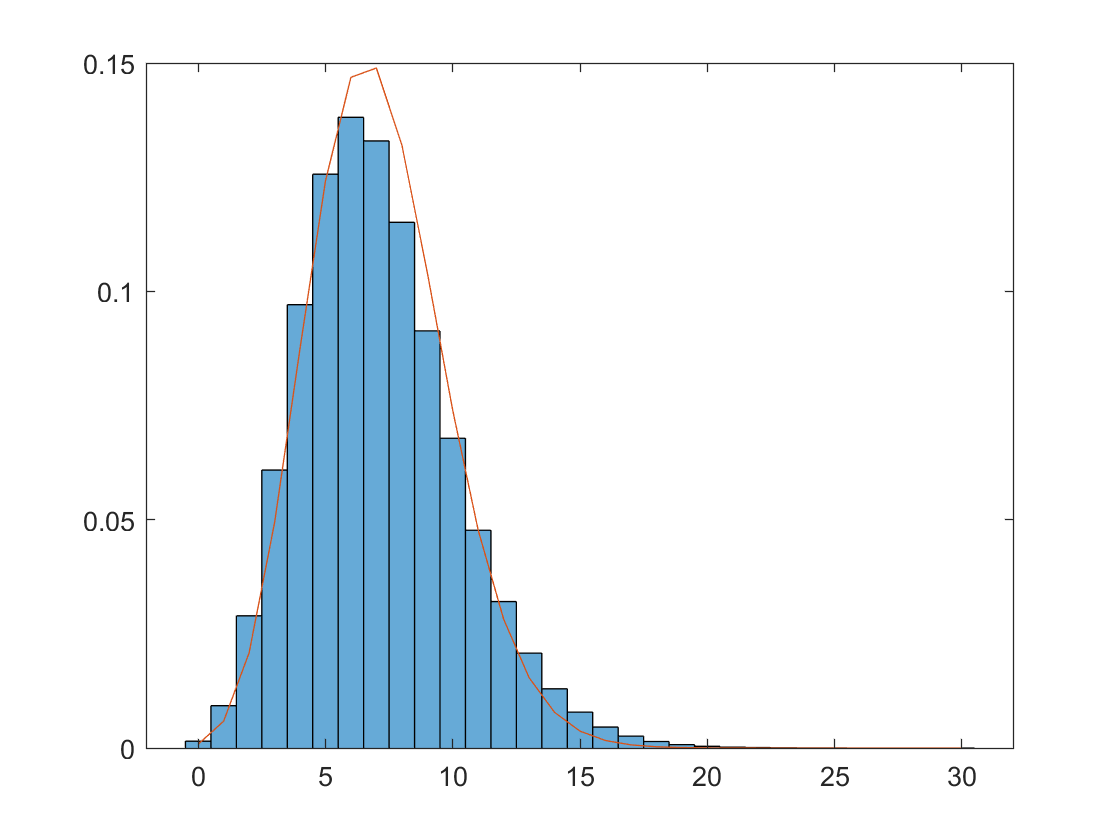

subplot(1,1,1)
histogram(counts,'Normalization','pdf')
hold on
xes = 0:1:30;
pd = makedist('Poisson','lambda',lam);
plot(xes,pdf(pd,xes))
hold off

2) The background is **not** consistent across the dataset. Find and describe as accurately as you can how the background changes.

Background changes with earth longitude, as seen in the graph above

- take sections and plot counts background distribution for that segment

- see how condition shifts 

- 2592001 data points

- compare 1000 data point intervals @start, some in middle, end

- plot means

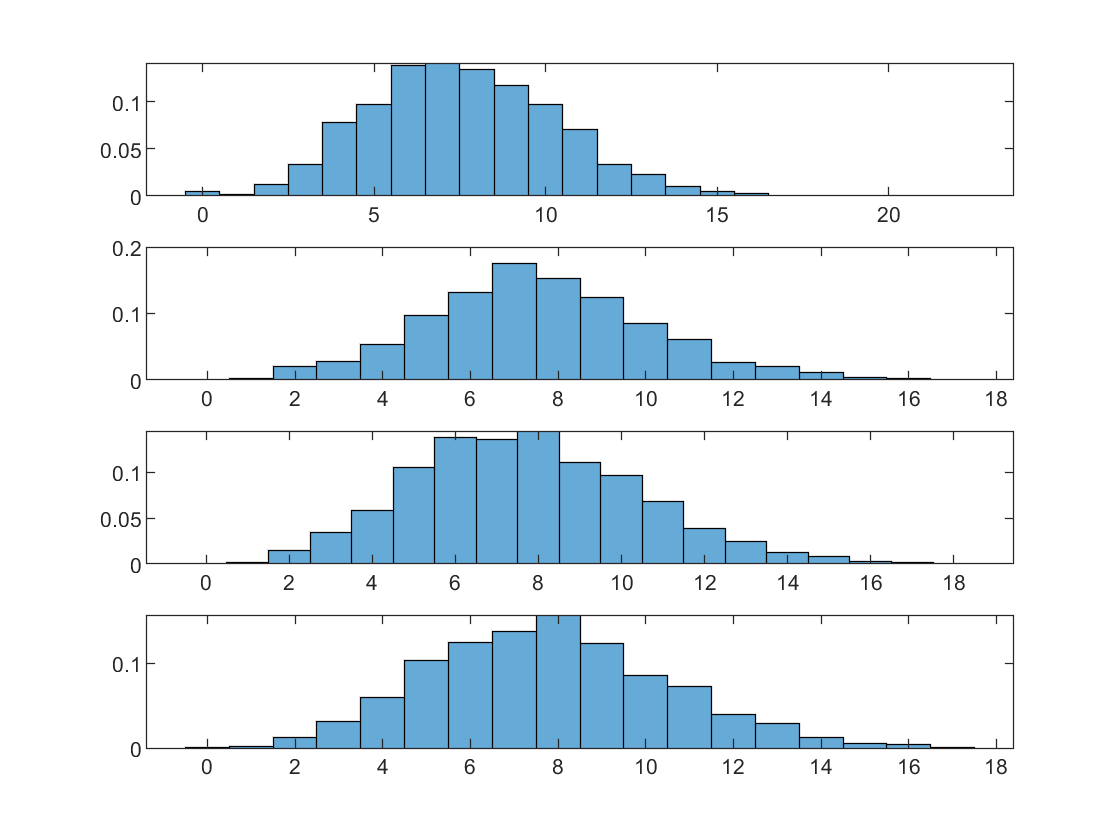

c1 = mydata(1:1000,4);

c2 = mydata(648001:649000,4);

c3 = mydata(1296001:1297000,4);

c4 = mydata(2591002:2592001,4);

subplot(4,1,1)
histogram(c1,'Normalization','pdf')
subplot(4,1,2)
histogram(c2,'Normalization','pdf')
subplot(4,1,3)
histogram(c3,'Normalization','pdf')
subplot(4,1,4)

histogram(c4,'Normalization','pdf')


l1 = 7.5990

l1 = mean(c1)

l2 = 7.5840

l2 = mean(c2)

l3 = 7.7330

l3 = mean(c3)

l4 = 7.7780

l4 = mean(c4)

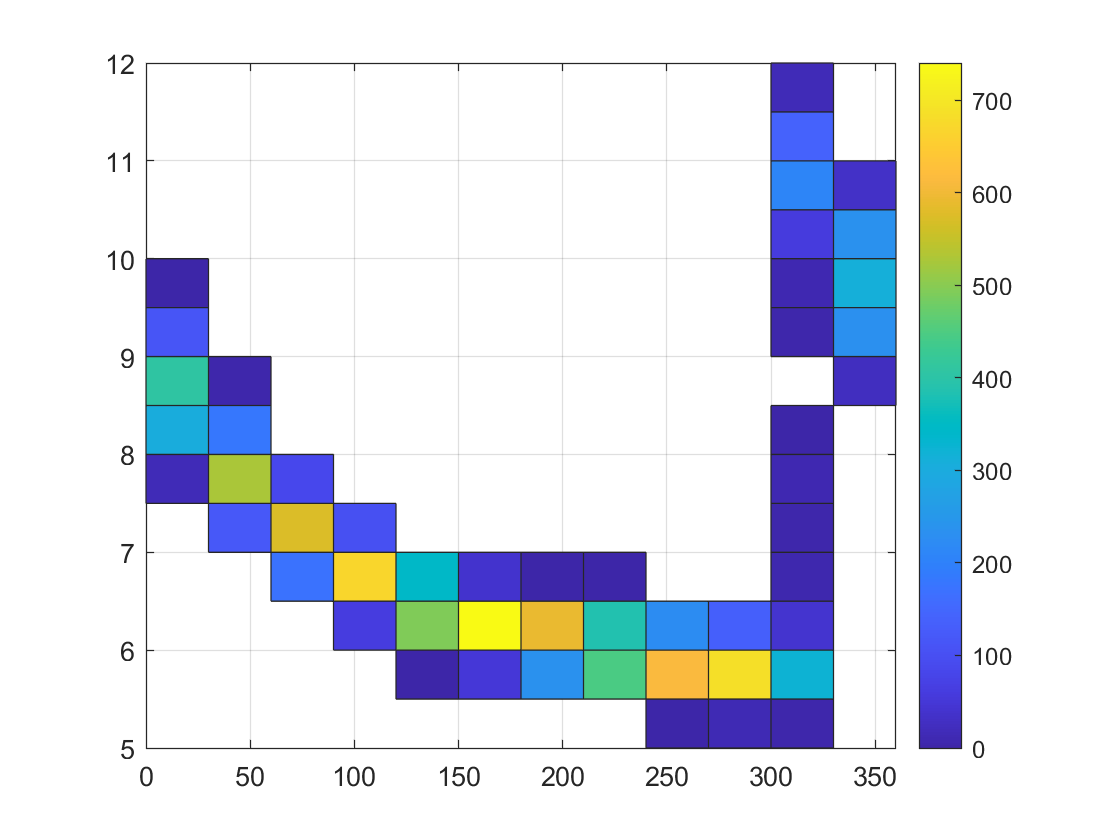

cmeans = zeros(10008,1);

for i = 0:10007
    cmeans(i+1,1) = mean(mydata((259*i+1):(259*(i+1)),4));
end

elpoints = mydata(1:259:2592001,3);

subplot(1,1,1)
histogram2(elpoints,cmeans,'DisplayStyle','tile')
colorbar

OBSERVATIONS

- means follow counts vs el

3) Create a model for the background that includes time dependence, and explicitly compare your model to the data. How good is your model of the background?

- earth longitude is time dependent (periodic function)

subplot(1,1,1)
plot(time(40000:105000),earthlong(40000:105000))

So one period for earthlong is about t = 5500

some graphs of distributions in one period:

t = 9.40685 --> t = 9.40686

and

t = 9.40689 --> t = 9.40690

4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times?

Optional: while this is simulated data, it is based on a real effect seen by low Earth orbit satellites. Can you identify the cause of the variable background and propose a physical model?

## Problem 2

In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be looking for different signals. One of you will be looking for the faintest stars, while the other will be looking for a transient (something like a super novae that only appears in one image). Flip a coin to determine which of you is pursuing which question.

1) Dowload the data from `images.h5`. This is a stack of 10 square images, each 200 pixels on a side.

h5disp('images.h5')
image1 = h5read('images.h5','/image1');

HDF5 images.h5 
Group '/' 
    Dataset 'image1' 
        Size:  200x200
        MaxSize:  200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000
    Dataset 'imagestack' 
        Size:  10x200x200
        MaxSize:  10x200x200
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


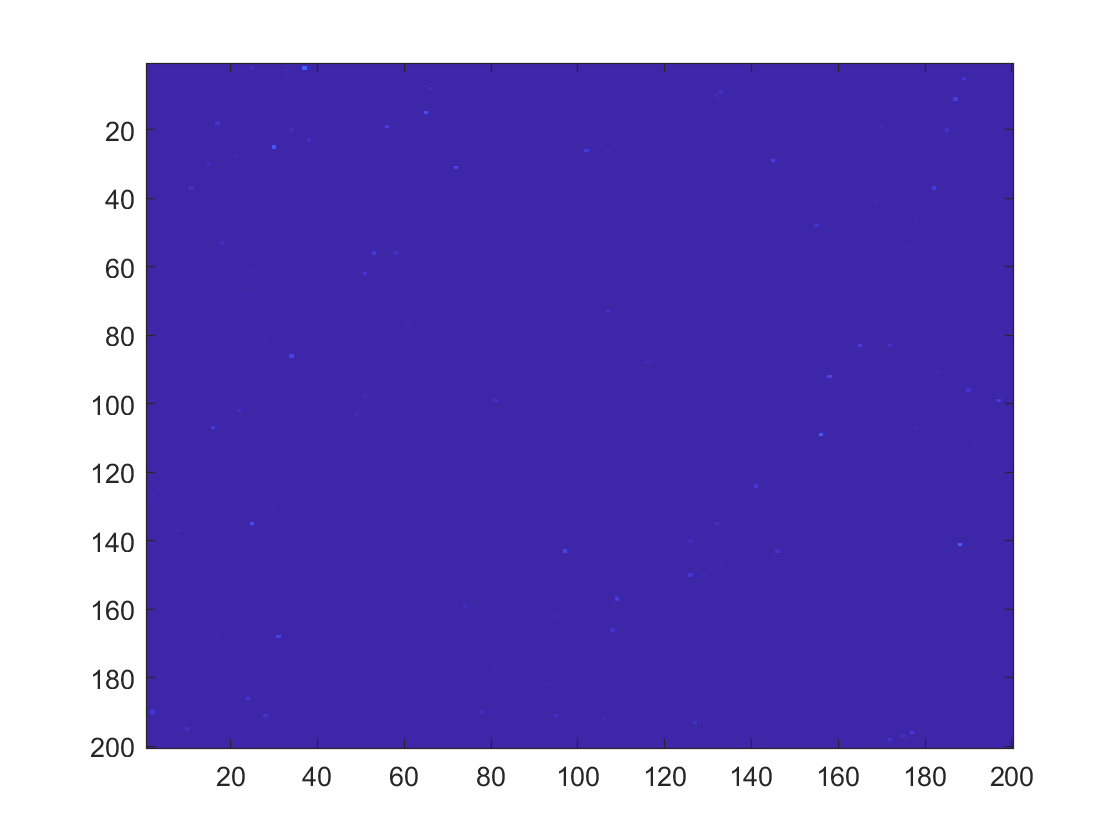

image(image1)
imagestack = h5read('images.h5','/imagestack');

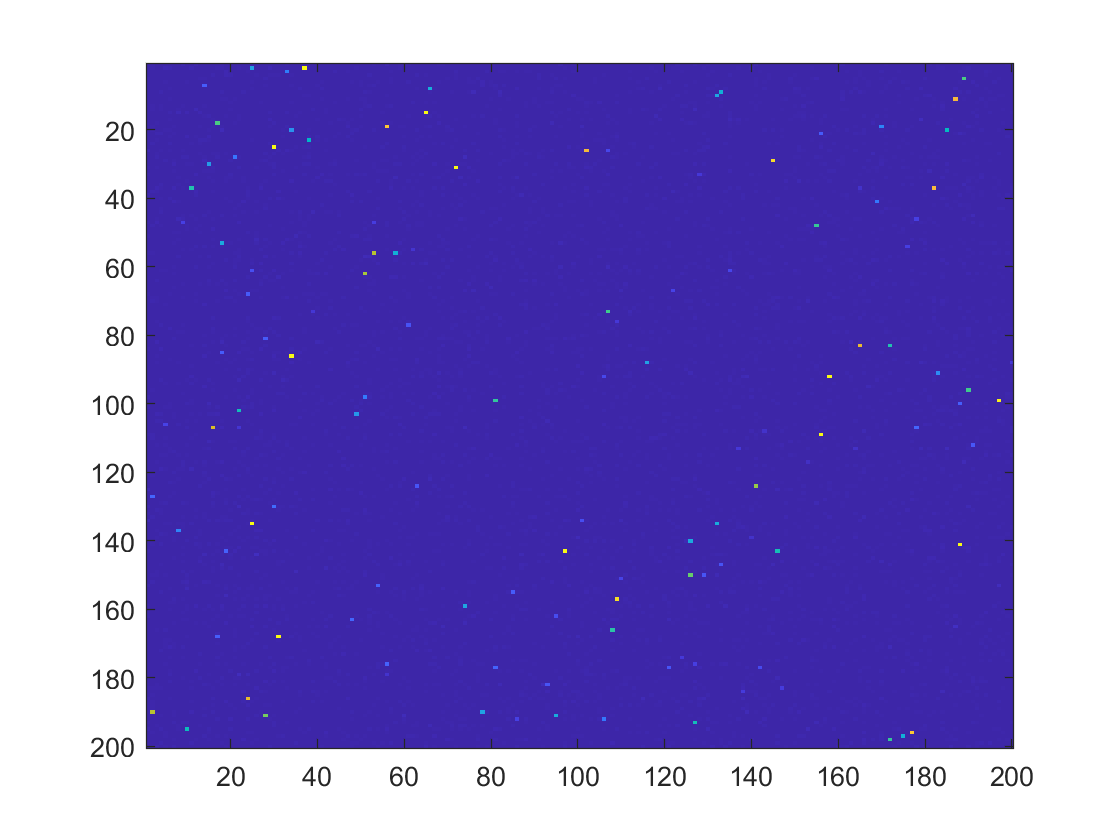

stack = zeros(200,200);

for k = 1:200
    for j = 1:200
        stack(k,j) = sum(imagestack(:,k,j));
    end
end

image(stack)

2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().

To calculate background pdf, 

- compress each individual image into a 1D background, average, plot 1D

- plot every pixel brightness (put all rows into a single column vector)

brightness = zeros(10,40000);

for b = 1:10
    for i = 1:200
        for h = 1:200
            brightness(b,i*h) = imagestack(b,i,h);
        end
    end
end

x = 1:40000;
brightness1 = brightness(1,:);
plot(x,brightness1)
hold on
for i = 2:10
    plot(x,brightness(i,:))
end
hold off

- background is just the static-y stuff, peaks are stars

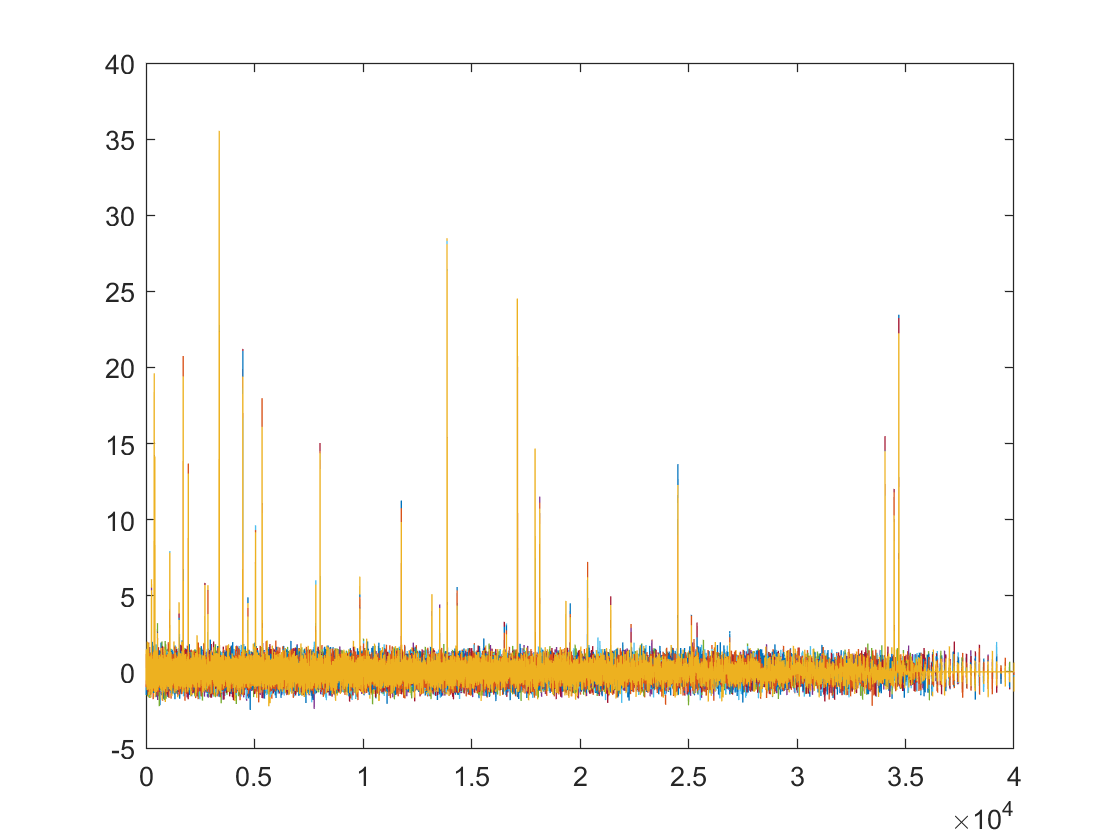

firstlast = zeros(200,200);


for m = 1:200
    for n = 1:200
        firstlast(m,n) = imagestack(1,m,n) - imagestack(10,m,n);
    end
end
image(firstlast)

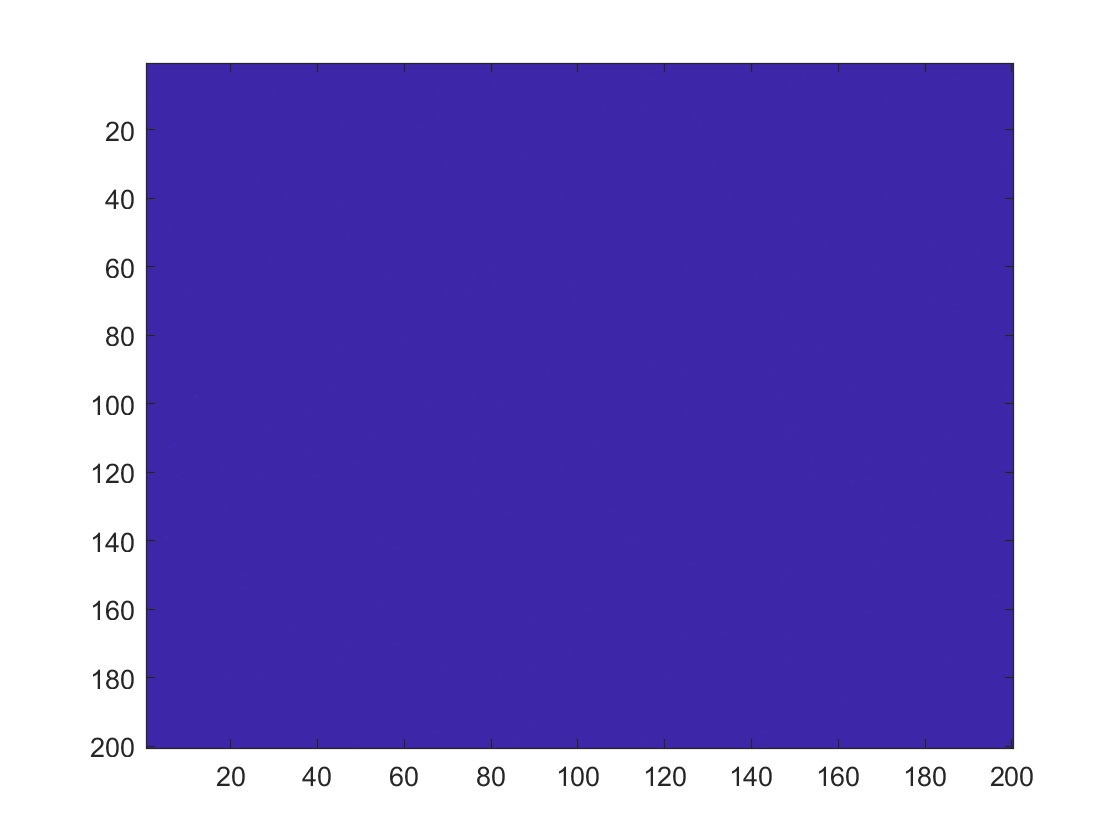

diff = zeros(1,40000);

for i = 1:200

    for h = 1:200
        diff(1,i*h) = firstlast(i,h);
    end
end

subplot(1,1,1)
plot(x,diff)

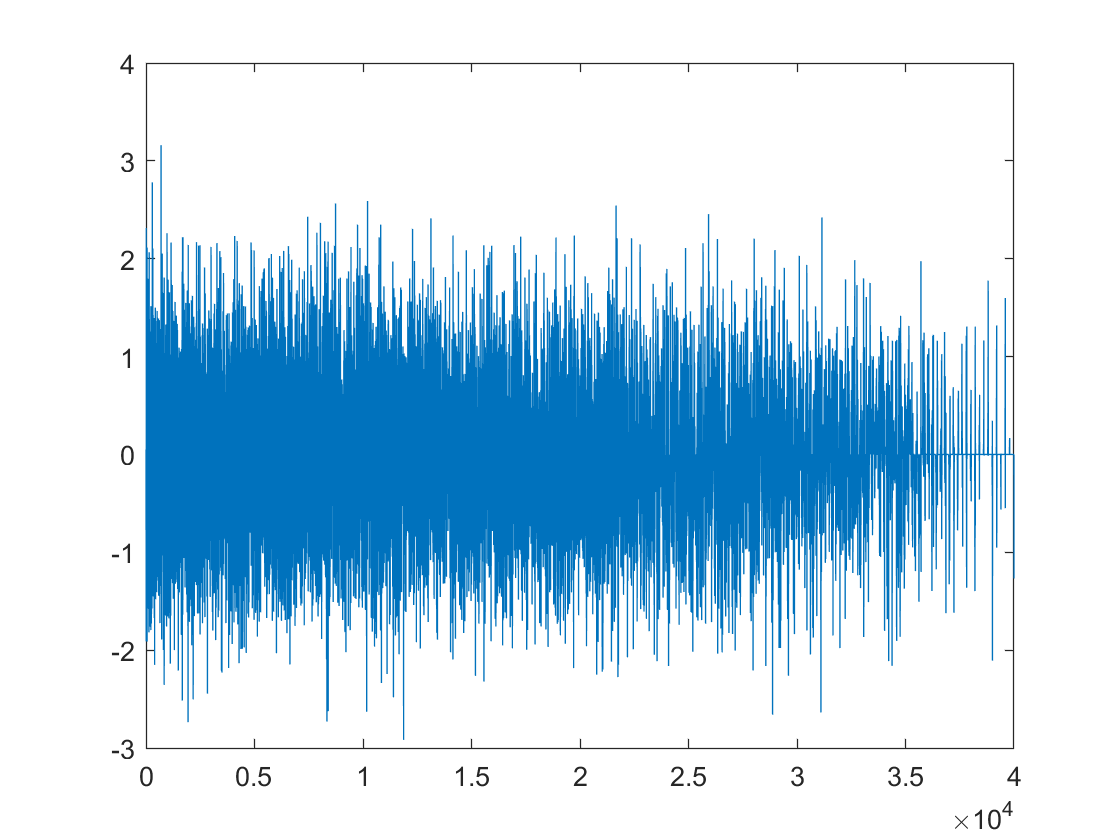

averaged = zeros(1,200);

for p = 1:200
    averaged(1,p) = sum(stack(p,:));

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


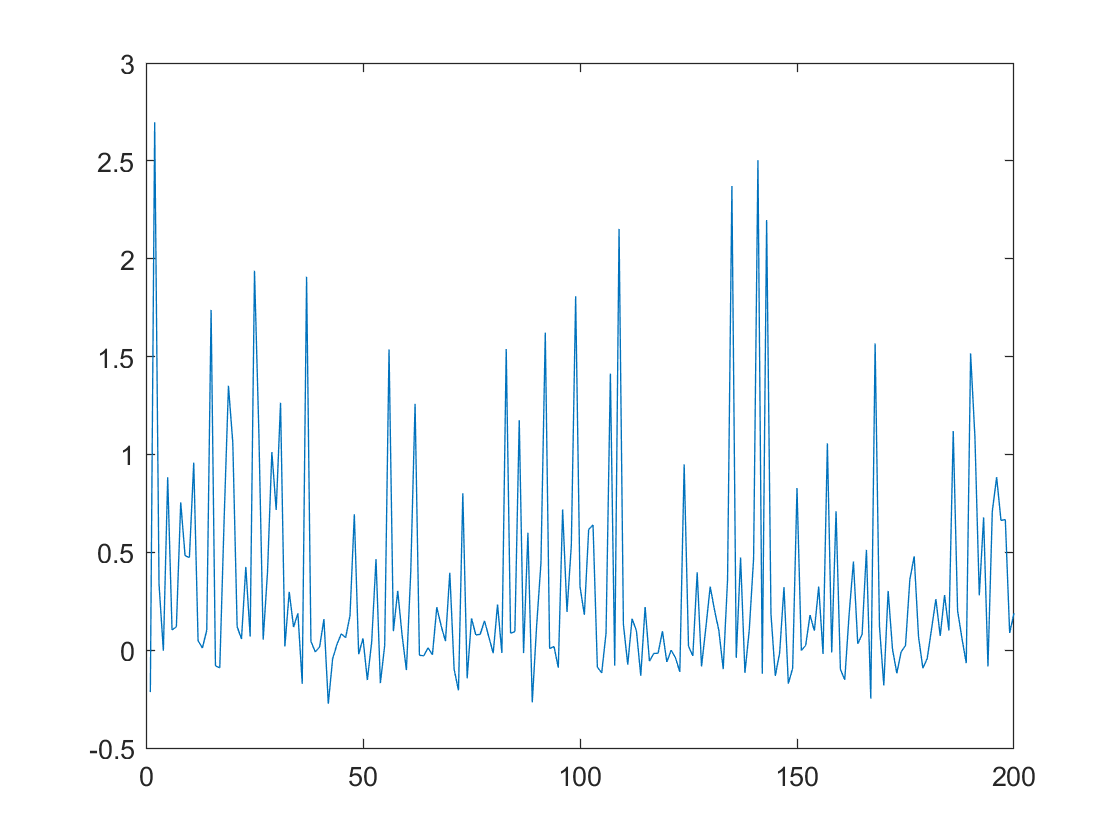

end

averaged = averaged/200;
x = 1:200;
subplot(1,1,1)
plot(x,averaged)

3) Using your background distribution, hunt for your signal (either faint stars, or a transient). Describe what you find.

4) You and your lab partner had different pdf(), but were using the *same* data. Explore why this is.